summary(Song)

Variables:

    Artist: 4850×1 string

    Title: 4850×1 string

    Year: 4850×1 double

        Values:

            Min         1901  
            Median      1981  
            Max         2014  

    Sales: 4850×1 double

        Values:

            Min         4.149 
            Median      6.438 
            Max        36.503 

    Streams: 4850×1 double

        Values:

            Min             0 
            Median        4.2 
            Max        25.545 

    Downloads: 4850×1 double

        Values:

            Min            0  
            Median       2.2  
            Max        19.78  

    RadioPlays: 4850×1 double

        Values:

            Min             0 
            Median       2.57 
            Max        24.393 

    Rating: 4850×1 double

        Values:

            Min            0  
            Median     0.512 

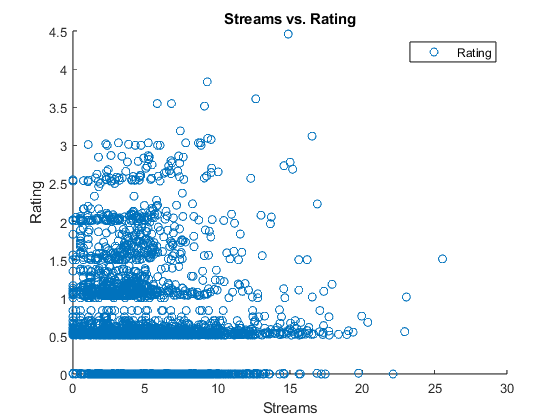

% Create scatter of Song.Streams and Song.Rating
s = scatter(Song.Streams,Song.Rating,'DisplayName','Rating');

% Add xlabel, ylabel, title, and legend
xlabel('Streams')
ylabel('Rating')
title('Streams vs. Rating')
legend

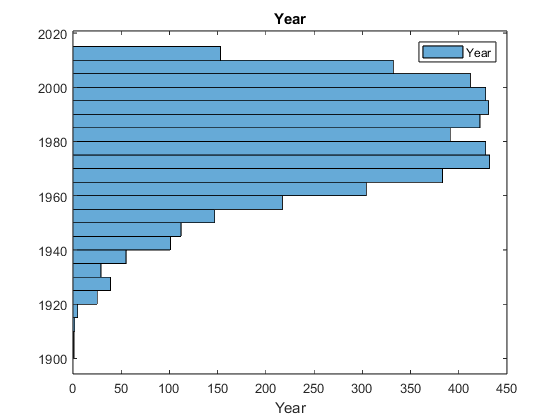

% Create histogram of Song.Year
h = histogram(Song.Year,'Orientation','horizontal','DisplayName','Year');

% Add xlabel, and title
xlabel('Year')
title('Year')
legend

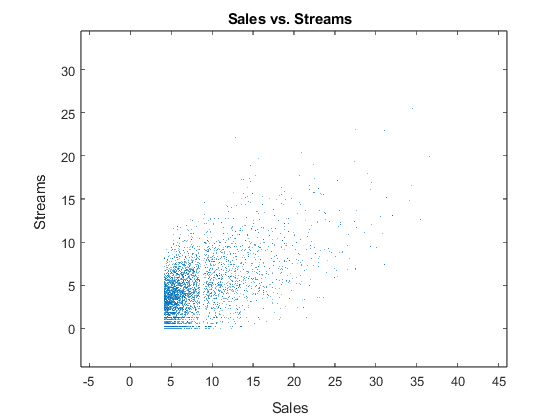

% Create plotmatrix of Song.Sales and Song.Streams
[S2,AX2,BigAx2,H2,HAx2] = plotmatrix(Song.Sales,Song.Streams);

% Add xlabel, ylabel, and title
xlabel('Sales')
ylabel('Streams')
title('Sales vs. Streams')

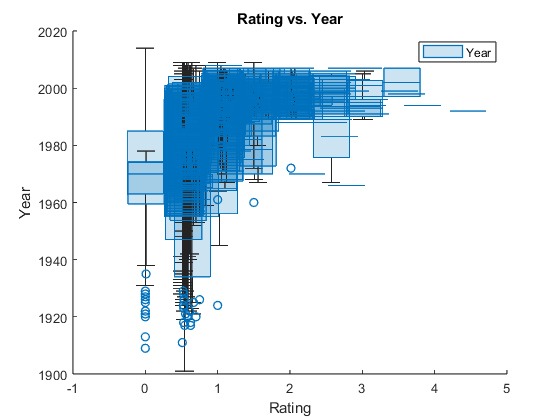

% Create boxchart of Song.Rating and Song.Year
h2 = boxchart(Song.Rating,Song.Year,'DisplayName','Year');

% Add xlabel, ylabel, title, and legend
xlabel('Rating')
ylabel('Year')
title('Rating vs. Year')
legend

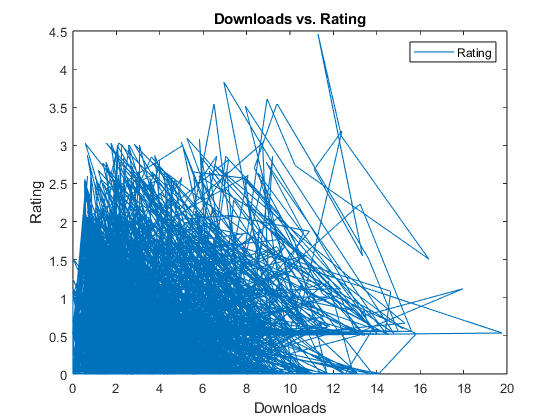

% Create plot of Song.Downloads and Song.Rating
h3 = plot(Song.Downloads,Song.Rating,'DisplayName','Rating');

% Add xlabel, ylabel, title, and legend
xlabel('Downloads')
ylabel('Rating')
title('Downloads vs. Rating')
legend

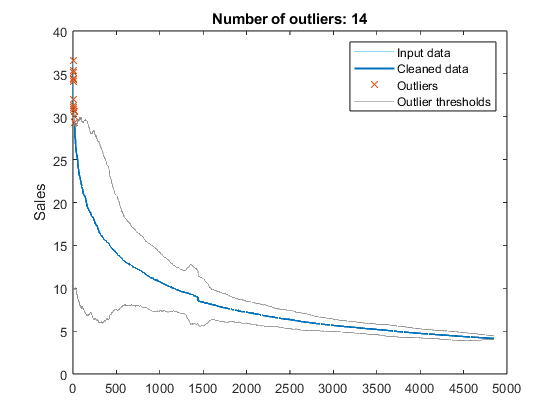

% Remove outliers
[newTable,outlierIndices] = rmoutliers(Song,"movmedian",610,...
    "DataVariables","Sales");

% Display results
clf
plot(Song.Sales,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(find(~outlierIndices),newTable.Sales,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),Song.Sales(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(Song.Sales,"movmedian",610);

% Plot outlier thresholds
plot([(1:numel(Song.Sales))'; missing; (1:numel(Song.Sales))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],"Color",[145 145 145]/255,...
    "DisplayName","Outlier thresholds")

hold off
legend
ylabel("Sales")

clear thresholdLow thresholdHigh

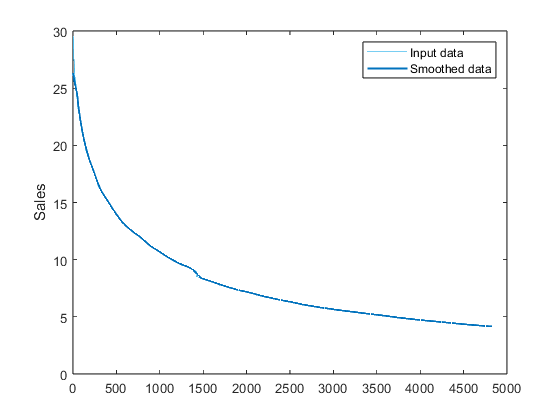

% Smooth input data
newTable2 = smoothdata(newTable,"movmean","SmoothingFactor",0.04999999999999999,...
    "DataVariables","Sales");

% Display results
clf
plot(newTable.Sales,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(newTable2.Sales,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
ylabel("Sales")

idx = 0.2

idx = 0.2000

hpartition = cvpartition(length(newTable2.Rating), 'HoldOut',idx)

hpartition = Hold-out cross validation partition
   NumObservations: 4836
       NumTestSets: 1
         TrainSize: 3869
          TestSize: 967

idxTrain = training(hpartition);
trainData = newTable2(idxTrain,:)

trainData = 3869×8 table
            Artist                       Title               Year    Sales     Streams    Downloads    RadioPlays    Rating
    _______________________    __________________________    ____    ______    _______    _________    __________    ______

    "The Beatles"              "Let it Be"                   1970    26.242    16.881      13.234        15.888      2.231 
    "Procol Harum"             "A Whiter Shade of Pale"      1967    26.192    12.018      15.602        16.833      0.558 
    "Bee Gees"                 "Stayin' Alive"               1978    26.145     16.16      12.874        17.865      0.571 
    "The Police"               "Every Breath You Take"       1983    26.098    17.

idxTest = test(hpartition);
testData= newTable2(idxTest,:)

testData = 967×8 table
                   Artist                                 Title                  Year    Sales     Streams    Downloads    RadioPlays    Rating
    ____________________________________    _________________________________    ____    ______    _______    _________    __________    ______

    "Usher"                                 "Yeah!"                              2004    26.291    14.647         8.4        13.727          1 
    "John Travolta & Olivia Newton-John"    "You're the One That I Want"         1978    25.647     8.046      14.992        22.145      0.555 
    "USA For Africa"                        "We Are the World"                   1985    25.606    10.855      13.627        18.

testAnswers = testData.Rating;
testData = removevars(testData,"Rating")

testData = 967×7 table
                   Artist                                 Title                  Year    Sales     Streams    Downloads    RadioPlays
    ____________________________________    _________________________________    ____    ______    _______    _________    __________

    "Usher"                                 "Yeah!"                              2004    26.291    14.647         8.4        13.727  
    "John Travolta & Olivia Newton-John"    "You're the One That I Want"         1978    25.647     8.046      14.992        22.145  
    "USA For Africa"                        "We Are the World"                   1985    25.606    10.855      13.627        18.761  
    "Spice Girls"                           "Wannabe"               

regressionLearner

trainedModel

trainedModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Artist'  'Downloads'  'RadioPlays'  'Sales'  'Streams'  'Title'  'Year'}
         RegressionGP: [1×1 RegressionGP]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


justModel = trainedModel.RegressionGP

justModel =   RegressionGP
           PredictorNames: {'Artist'  'Title'  'Year'  'Sales'  'Streams'  'Downloads'  'RadioPlays'}
             ResponseName: 'Y'
    CategoricalPredictors: [1 2]
        ResponseTransform: 'none'
          NumObservations: 3869
           KernelFunction: 'RationalQuadratic'
        KernelInformation: [1×1 struct]
            BasisFunction: 'Constant'
                     Beta: 0.3976
                    Sigma: 0.0061
        PredictorLocation: [5553×1 double]
           PredictorScale: [5553×1 double]
                    Alpha: [3869×1 double]
         ActiveSetVectors: [3869×5553 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 2000
                FitMethod: 'SD'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [3869×1 logical]
            LogLikelihood: -815.3931
         ActiveSetHistory: [1×1 struct]
           BCDInformation: []


  

predictedRating= trainedModel.predictFcn(testData);
testErrors= testAnswers - predictedRating;
%testAvgError=sum(abs(testErrors)) ./length(testAnswers)
testLoss= loss(justModel,testData,testAnswers)

testLoss = 0.1131

trainLoss = loss(justModel,trainData,trainData.Rating)

trainLoss = 1.1170e-08

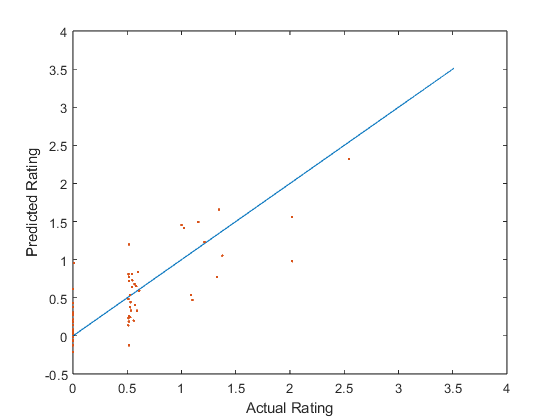

plot(testAnswers, testAnswers);
hold on
plot(testAnswers,predictedRating,".");
hold off
xlabel('Actual Rating');
ylabel('Predicted Rating');

trainAbove1= numel(trainData.Rating(trainData.Rating>1))

trainAbove1 = 691

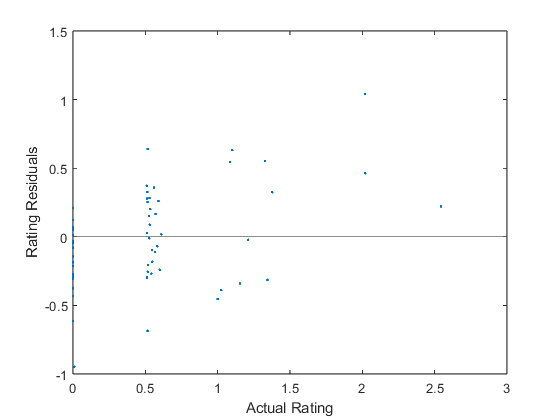

plot(testAnswers,testErrors,".")
hold on
yline(0)
hold off
xlabel('Actual Rating')
ylabel('Rating Residuals')

testData(testErrors>0.5 | testErrors<-0.5,:)

ans = 8×7 table
             Artist                        Title               Year    Sales     Streams    Downloads    RadioPlays
    ________________________    ___________________________    ____    ______    _______    _________    __________

    "The Righteous Brothers"    "Unchained Melody"             1965    23.712    15.616       9.239         7.075  
    "Abba"                      "Waterloo"                     1974    19.807     6.399       7.007        17.425  
    "Des'ree"                   "Life"                         1998    9.2201         0       1.145        14.626  
    "Nickelback"                "Someday"                      2003    7.3335     3.642       2.833         3.327  
    "Madonna"                   "Cherish"        

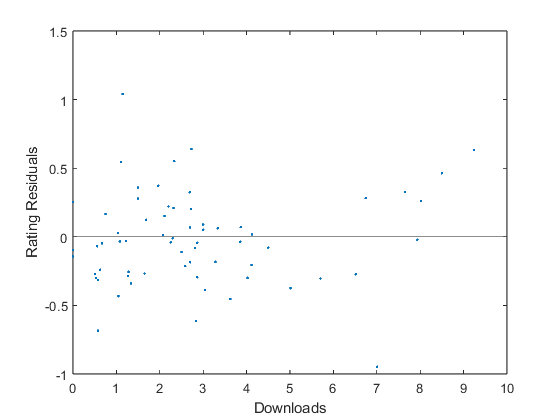

plot(testData.Downloads, testErrors, ".");
hold on 
yline(0)
hold off
xlabel('Downloads')
ylabel('Rating Residuals')

model_song= trainedModel;
save model_song;

Error using save
Unable to save file 'D:\MATLAB ML\model_song.mat'. The file could not be closed, and might now be corrupt.